# Motion Architectures

## Lane change

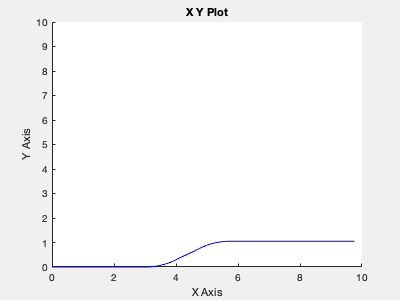

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


clear
sl_lanechange
out=sim("sl_lanechange.slx")

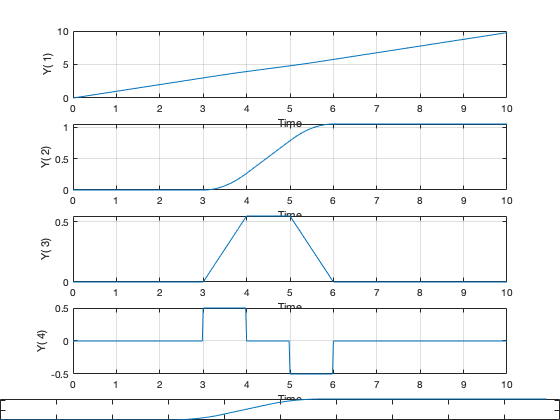

t = out.get('t'); q = out.get('y');
mplot(t, q)
plot(q(:,1), q(:,2))

## Moving to a point

clear
%sl_drivepoint
xg = [3 1];
x0 = [8 5 pi/2];
K_V=0.5

K_V = 0.5000

K_S=4

K_S = 4

r1=sim("sl_drivepoint.slx")

r1 =   Simulink.SimulationOutput:

                      t: [55x1 double] 
                      y: [55x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


q_05_4= r1.find('y');
K_V=0.5

K_V = 0.5000

K_S=1

K_S = 1

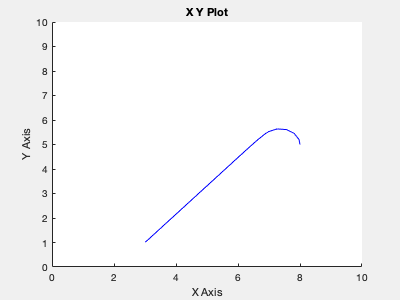

r2 =   Simulink.SimulationOutput:

                      t: [55x1 double] 
                      y: [55x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


r2=sim("sl_drivepoint.slx")

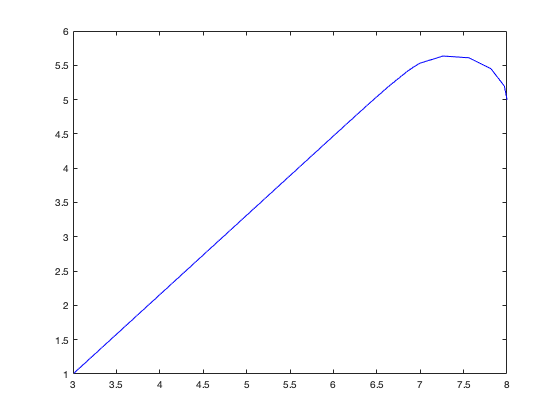

q_1_4= r2.find('y');
plot(q_05_4(:,1), q_05_4(:,2),'r');
hold on
plot(q_1_4(:,1), q_1_4(:,2),'b');

## Following a line

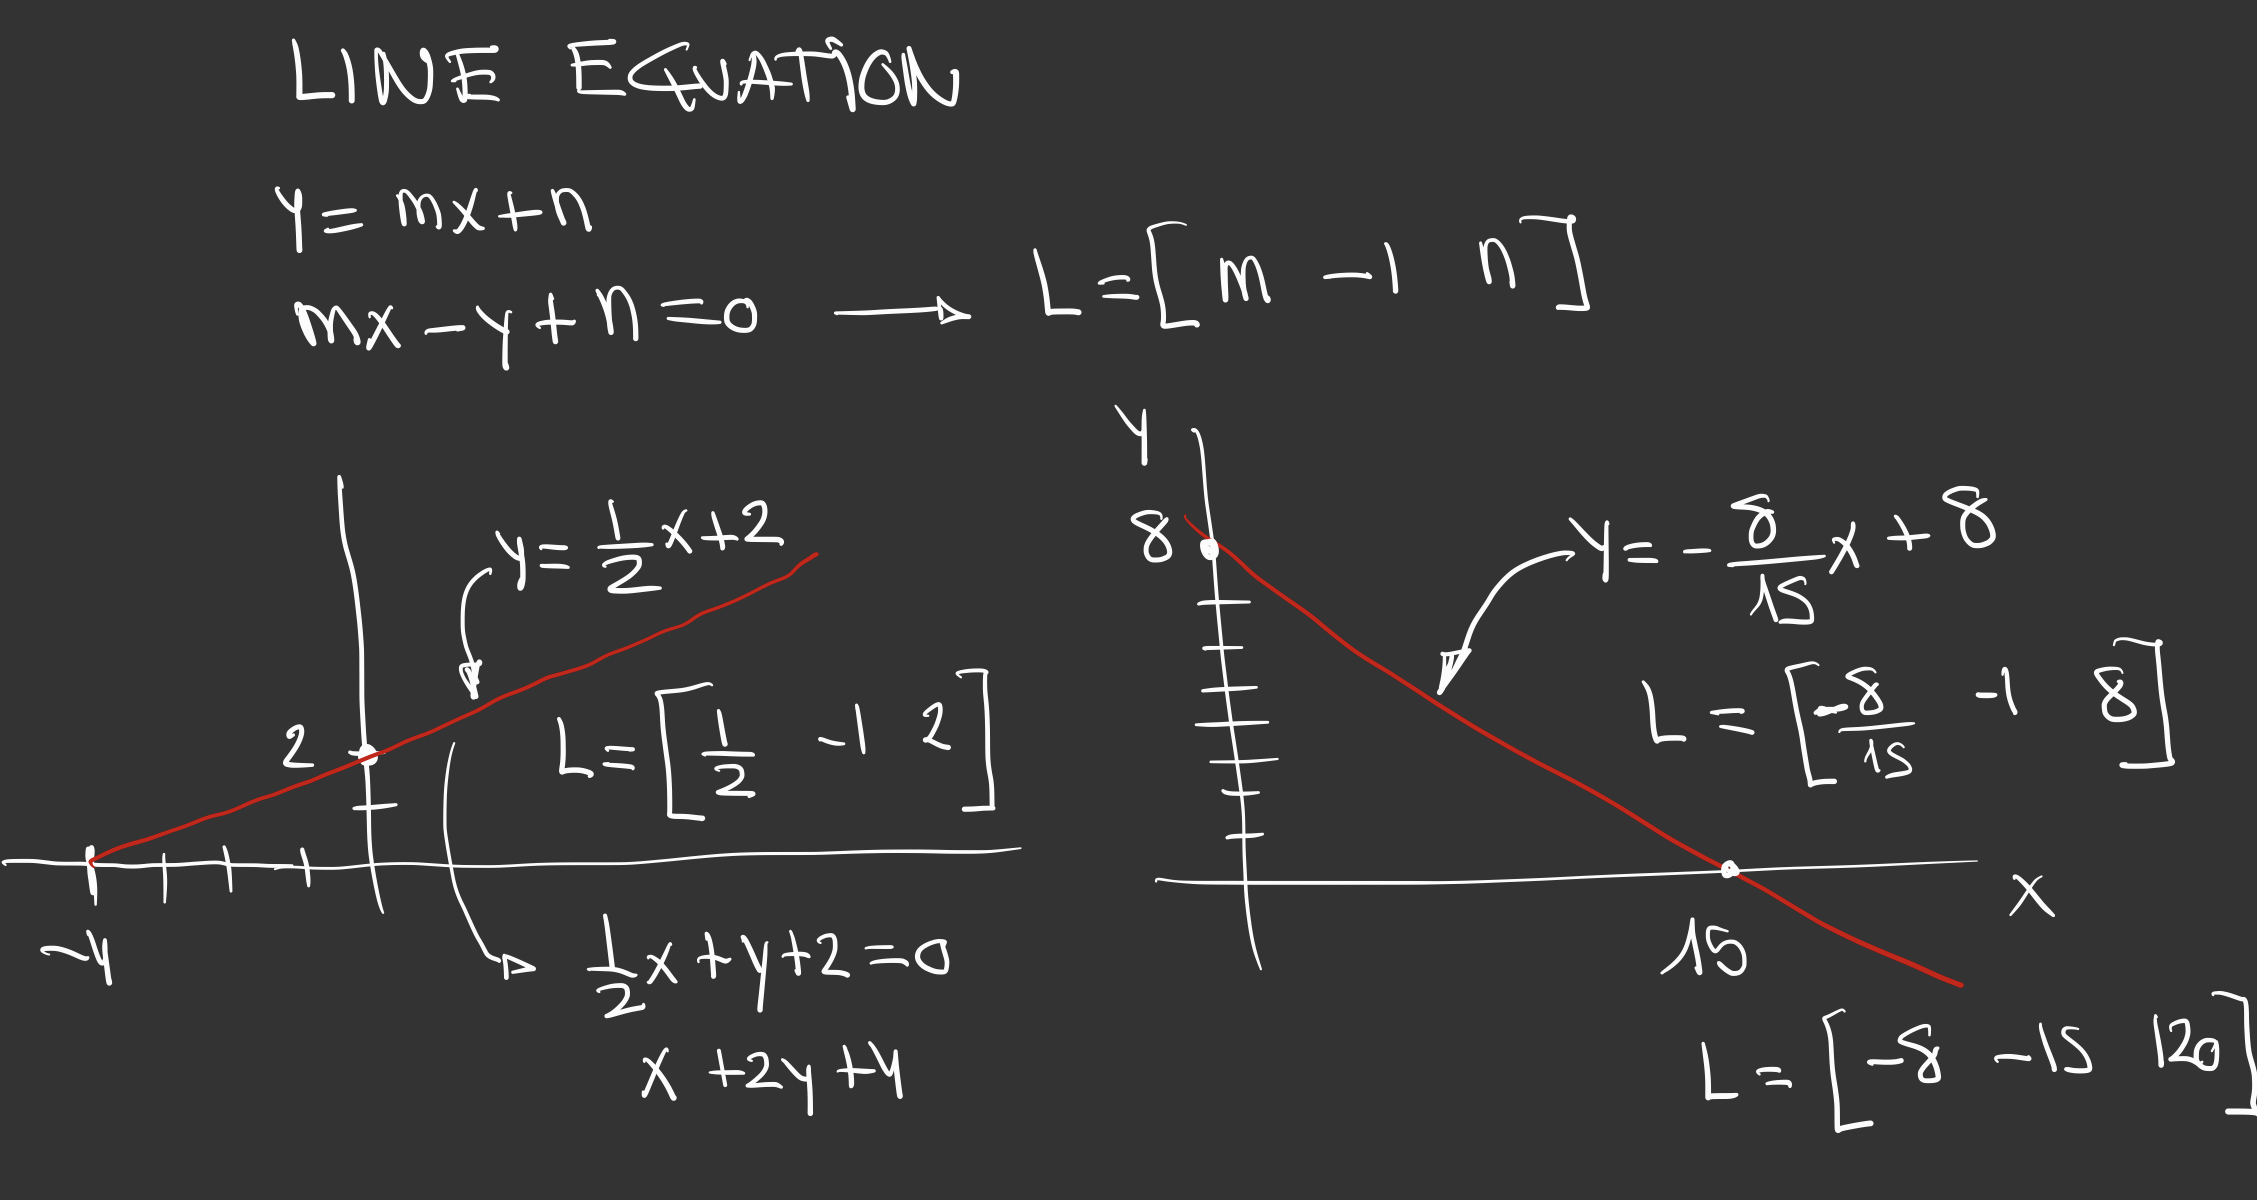

clear
sl_driveline
x0=[8 5 pi/2]

x0 =     8.0000    5.0000    1.5708


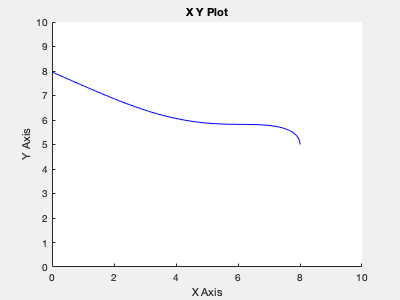

ans =   Simulink.SimulationOutput:

                      t: [503x1 double] 
                      y: [503x2 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


L = [-8/15 -1 8]; 
sim("sl_driveline.slx")

## Following a trajectory

Read Chapter 4 of the Peter corke Book

## Moving to a pose

Read Chapter 4 of the Peter corke Book